# Progetto: stabilizzazione, identificazione e controllo MPC di un pendolo inverso su carrello

#include

addpath('./functions');   %sottocartella con funzioni

### Descrizione del problema

Il **sistema** di studio sarà la seguente composizione: pendolo inverso libero di ruotare ancorato ad un carrello libero di traslare.

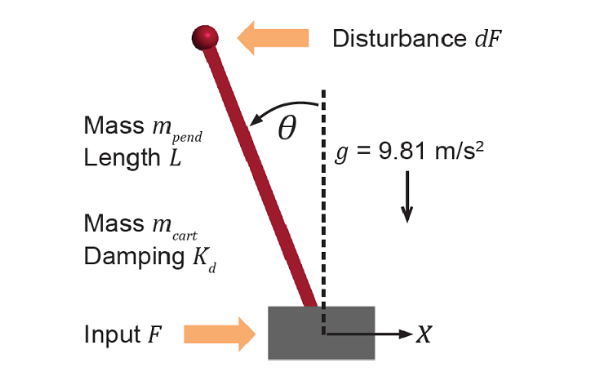

dove i **dati sperimentali **(ideali) del modello sono:

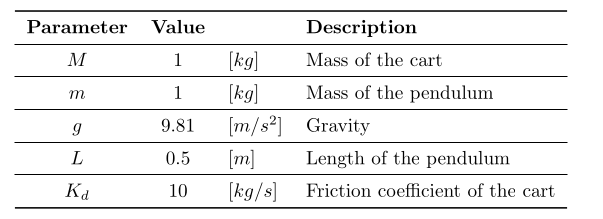

M = 1; m = 1; g = 9.8; L = 0.5; Kd = 10;

Si considerino i seguenti **segnali**

- F = forza in ingresso su carrello (controllo)

- x e teta = spostamento lineare del cart e spostamento angolare del pendolo (misurabili e da regolare).

- df = forza di disturbo sul pendolo (disturbo)

**Modelliamo i sensori **che restituiscono la misura di x e teta.

Ipotizziamo alcune caratteristiche:

- errore massimo di misura di posizione x: 3cm

- errore massimo di misura di pos. ang. teta: 0.02° (50esimo di grado)

- tempo di campionamento sens. posizione: 0.002s

- tempo di campionamento sens. pos. ang: 0.002s

- ritardo di misura sensori: 1e-6 s

%tarati i noise power finché il blocco "White Noise" 
% di simulink abbia restituiti rumori di ampiezza giusta
x_noise_power =  1.4576e-09

x_noise_power = 1.4576e-09

teta_noise_power = 1.6046e-11

teta_noise_power = 1.6046e-11


%tempi di campionamento
Ts_sens_x = 0.002;
Ts_sens_teta = 0.002;

%ritardo di misura di entrambi
ritardo_misura = 1e-6; %[s]

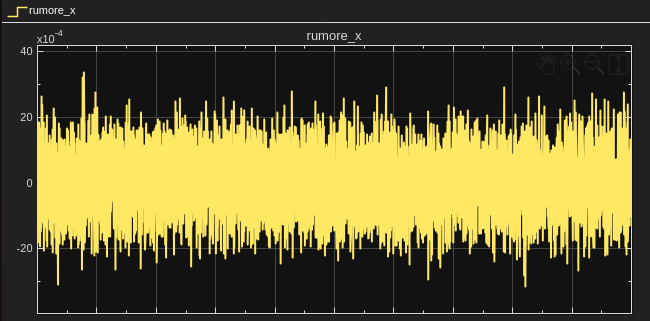

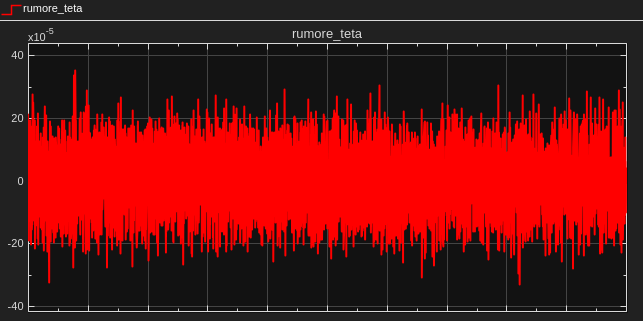

Il sistema deve lavorare attorno al **punto d'equilibrio **

- Stato d'equilibrio  x = 0  Teta = 0  

- Ingressi d'equilibrio F = 0  dF = 0 

**Nota: **Intuitivamente è punto d'equilibrio dal punto di vista fisico, ma è possibile verificare che è soluzione imponento tutte le derivate uguali a 0 nelle equazioni differenziali.

**Limitazioni **del sistema:

- Limite dell'attuatore $-200 < F <200$ [N]

- Limite della rotaia del carrello $-10<x<10$ [m]

%limiti attuatore 
limite_sup_att = 200;
limite_inf_att = -200;

**Nota: **i limiti dell'attuatore saranno modellati con un blocco saturazione in simulink 

Puoi vedere l'implementazione di quanto trattato al modello simulink [./simulink_models/sistema_con_reazione_stato.slx](matlab:open('./simulink_models/sistema_con_reazione_stato.slx'))

### Implementazione del modello fisico su simulink

Le **equazioni dinamiche** del modello trovate sono:

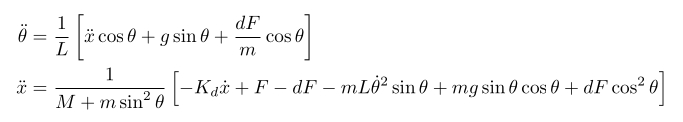

Queste verranno usate per simulare il sistema fisico su simulink: [./simulink_models/sistema_pendolo_carrello.slx](matlab:open('./simulink_models/sistema_pendolo_carrello.slx'))

**Nota: **Nel nostro esercizio, questo modello dobbiamo far finta di non conoscerlo, per poi identificarlo.

In pratica stiamo "simulando" un approccio "hardware in the loop", come se questo blocco, fosse il sistema vero e proprio.

### **Stabilizzazione del sistema attorno all'equilibrio, scelta della strategia**

Siccome il sistema è in un punto di equilibrio instabile, l'identificazione non è possibile, siccome è impossibile perturbare il sistema senza che questo diverga.

L'unica possibilità che abbiamo per identificarlo e controllarlo, è **realizzare un controllore empirico che lo stabilizzi intorno al punto d'equilibrio**.

Scelta della tecnica di stabilizzazione:

- L'instabilità del modello, non ci permette di effettuare tentativi di stabilizzazione alla Ziegler e Nichols (taratura in anello chiuso) -> **SCARTATO**

- Usare un controllore PID non è la scelta più semplice, in quanto il sistema non è SISO (dovrei cioè tararne più di uno e chiudere dei loop innestati per controllarne poi altri) -> **SCARTATO**

Ci rimane da tentare un **feedback di stato**.

Scelte le variabili di stato e gli ingressi come:

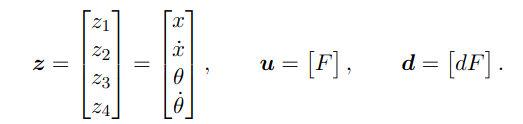

Stiamo cercando quindi **K = [k1 k2 k3 k4]  **tale che il controllo **u = -K*z **stabilizzi il sistema.

Gli stati z2 e z4 (ovvero $\dot{x}$ e $\dot{\theta}$) non sono accessibili e quindi vanno stimati con un **derivatore in banda**. 

Tau non deve essere troppo grande sia per un problema di costo d'implementazione, sia perché altrimenti il sistema passa alto amplificherebbe troppo i rumori di misura, in alta frequenza.


$$G_ {DER} = \frac{s}{1+\tau s}$$


Con una taratura è stato scelto a:

tau_derivatore = 0.02; %punto di rottura a 50 rad/s
Gder = tf([1 0], [tau_derivatore 1])


Gder =
 
      s
  ----------
  0.02 s + 1
 
Continuous-time transfer function.


In questa fase supporremo di poter tenere d a zero (ovvero di essere in un ambiente isolato e controllato).

### Cerca dei coefficienti: algoritmo genetico

**L'idea è ottimizzare la risposta in simulazione del sistema controllato, in una situazione di instabilità**.

Per semplicità si è scelto quando il pendolo è ad un grado (1°) dalla sua normale.

I coefficienti verranno trovati con un **algoritmo genetico **che minimizza la seguente fitness.

function fitness = fitness_pendolo(K)

    % Assegna variabile al modello Simulink
    assignin('base', 'k1', K(1));
    assignin('base', 'k2', K(2));
    assignin('base', 'k3', K(3));
    assignin('base', 'k4', K(4));

    
    % Esegui la simulazione di Simulink
    simOut = sim('./simulink_models/taratura_reazione_stato', 10); %10 secondi

    % Estrai dati di simulazione
    x_ts = simOut.get('x_sim'); 
    x_data = x_ts.Data;

    x_punto_ts = simOut.get('x_punto_sim'); 
    x_punto_data = x_punto_ts.Data;    

    teta_ts = simOut.get('teta_sim'); 
    teta_data = teta_ts.Data;
    tempo = teta_ts.Time; %lo estraggo una sola volta per tutti

    teta_punto_ts = simOut.get('teta_punto_sim'); 
    teta_punto_data = teta_punto_ts.Data; 

    % Calcola alcune statistiche della simulazione
    x_max = max(abs(x_data)); 
    teta_max = max(abs(teta_data));


    % Definisci le costanti di penalità e i limiti
    W_teta = 1000;      % Peso per l'angolo (priorità alta)
    W_x = 100;          % Peso per la posizione del carrello
    W_teta_punto = 50;  % Peso per la velocita' angolare
    W_x_punto = 10;     % Peso per la velocita' carrello
   
    TETA_LIMITE = pi/4; % 45 gradi, per considerare il sistema instabile
    X_LIMITE = 10;      % -10<x<10 è il limite della rotaia

    PENALITA_MAX = 1e6; % Penalità per fallimento estremo
    
    % --- 1. Penalità Estrema ---
    % Se il pendolo è caduto o il carrello è uscito, punisci in modo massiccio.
    if teta_max > TETA_LIMITE || x_max > X_LIMITE

k1 = -20.3018

k2 = -86.5900

k3 = 475.2216

k4 = 409.0522

        fitness = PENALITA_MAX; 
        return;                 % Fitness molto alta per scartare la soluzione
    end
    

    % --- 2. Componenti del Costo da Minimizzare ---

    %verranno calcolati dei "costi" sulla base dei quadrati delle risposte.
    %più si allontano da zero, e più questi costi sono alti -> soluzioni
    %pessime

    % Integrale del Quadrato dell'Angolo (Stabilizzazione)
    costo_teta = W_teta * trapz(tempo, teta_data.^2); 
    

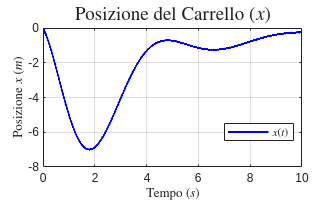

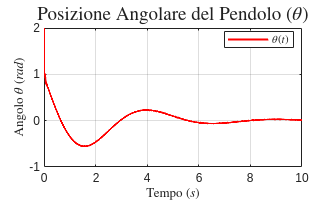

    % Integrale del Quadrato della Posizione (Contenimento del carrello)
    costo_x = W_x * trapz(tempo, x_data.^2);
    

    % Integrali dei quadrati delle velocità (smorzamento della risposta)
    costo_teta_punto = W_teta_punto * trapz(tempo, teta_punto_data.^2);
    costo_x_punto = W_x_punto * trapz(tempo, x_punto_data.^2);
    

    % --- 3. Fitness Totale ---
    fitness = costo_teta + costo_x + costo_teta_punto + costo_x_punto;

end

**Nota: **come possibile implementazione futura, potrei considerare anche il costo del controllo, così da prediligere tra due soluzioni, quella con un controllo più contenuto

Pronta la funzione di fitness, posso lanciare GA che la minimizzi e trovi K_ottimo. Durante questa trattazione, GA è stato già lanciato, con il seguente **risultato:**

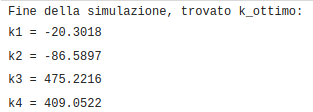

Dunque, setta il flag *launch_GA_flag*:

- a "true"  se vuoi rilanciare l'algoritmo con le tue opzioni personalizzate (spunta checkbox)

- a "false" se vuoi usare i valori già trovati (lascia senza spunta il checkbox)

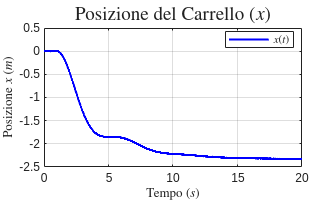

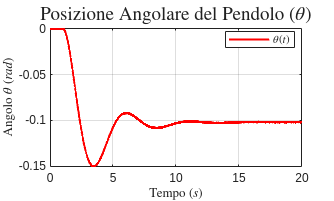

%flag di controllo
launch_GA_flag = false;    %vuota/spuntata=false/true


if(~launch_GA_flag) %uso i valori già trovati
    k1 = -20.3018
    k2 = -86.59
    k3 = 475.2216
    k4 = 409.0522
else                %lancio GA per la cerca di k_ottimo

    % 0. preparo la simulazione.

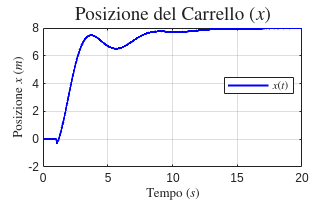

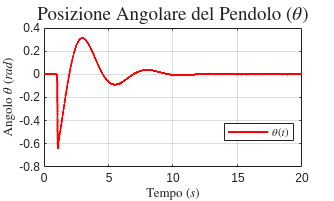

    set_input_simulink_trs(deg2rad(1), 0, 0, 0, 0);
    %no riferimento, no disturbo
    % endolo sfasato di 1 grado


    % 1. Limiti inferiori e superiori per i guadagni [k1 k2 k3 k4]
    lb = [-100, -100, -500, -500]; % Lower Bound (limite inferiore)
    ub = [100, 100, 500, 500];     % Upper Bound (limite superiore)
    
    % 2. Setto i parametri dell'algoritmo genetico
    MAX_TIME_SECONDS = 600;     %max 10 minuti d'esecuzione
    
    options = optimoptions('ga', ...
                           'PopulationSize', 80, ...
                           'MaxGenerations', 1000, ...  
                           'MaxTime', MAX_TIME_SECONDS, ... % <-- Arresto basato sul tempo
                           'FunctionTolerance', 1e-6); 
    
    % 3. Esegui l'algoritmo genetico
    [K_ottimo, fitness_min] = ga(@fitness_pendolo, 4, ...
                                   [], [], [], [], ...    
                                   lb, ub, ...            
                                   [], options);

    % 4. stampa del risultato
    disp('Fine della simulazione, trovato k_ottimo:');
    
    k1 = K_ottimo(1)
    k2 = K_ottimo(2)
    k3 = K_ottimo(3)
    k4 = K_ottimo(4)


    % post (ripristino le variabili modificate per la simulazione) 
    teta_zero = 0;
end


### Prove di stabilità

Una volta trovata k_ottimo, questo è il k che realizza la mia reazione di stato (LQR) e stabilizza il sistema intorno al punto d'equilibrio.

Posso testare il sistema in un po' di casi per certificare la bontà del risultato.

- 1° test: pendolo parte da posizione (molto) instabile

Facciamo partire il pendolo da un angolo molto lontano dalla normale (es 60°)

% setto l'input
set_input_simulink_trs(deg2rad(60), 0, 0, 0, 0); %teta_zero = 60°

% eseguo la simulazione
simOut = sim('./simulink_models/taratura_reazione_stato', 10); %10 secondi

% plot risposta
plot_x_teta(simOut);


Come previsto, sia x che teta si riportano alla posizione desiderata, in 0.

- 2° test: agisce un disturbo dF a gradino sul pendolo

% setto l'input
set_input_simulink_trs(0, 0, 0, 1, 1); %gradino di 1N ad 1s

% eseguo la simulazione
simOut = sim('./simulink_models/taratura_reazione_stato', 20); %10 secondi

% plot risposta
plot_x_teta(simOut);


In presenza del disturbo a gradino dF, x e teta si stabilizzano, ma con un errore a regime

- 3° test: seguire il riferimento in posizione

% setto l'input
set_input_simulink_trs(0, 8, 1, 0, 0); %g0radino0 di x=8 ad 1s

% eseguo la simulazione
simOut = sim('./simulink_models/taratura_reazione_stato', 20); %10 secondi

% plot risposta
plot_x_teta(simOut);


x segue correttamente il riferimento, mentre teta torna correttamente a zero.

### Conclusioni parte 1:

**Il sistema è stato stabilizzato con successo** attorno al punto d'equilibrio al fine di poterlo identificare.

Si vede dai grafici che il rumore sporca in modo molto leggero le risposte misurate (ci si accorge di leggere oscillazioni solo zoomando sulla risposta del sistema). Dunque abbiamo anche una **buona reiezione del rumore**, fondamentale per avere un'ottima identificazione.

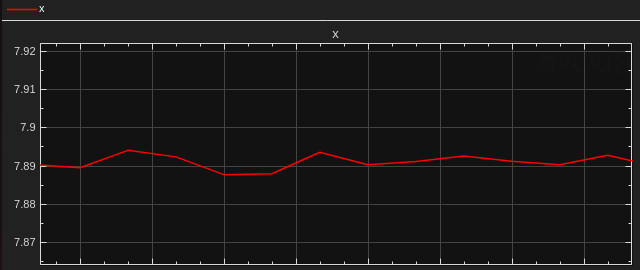

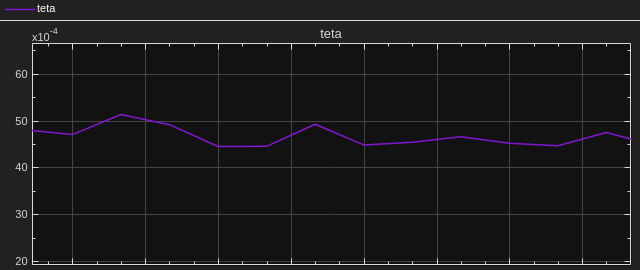

`Cosa fare adesso?  `

Passa al livescript [./identificazione.slx](matlab:open('./identificazione.slx'))

### Studente:

Schettini Francesco (A18000485)

### Esame

IDentificazione e Controllo dei Processi  - prof Cavallo Alberto - aa. 2025-26

### Università

Università degli studi della Campania Luigi Vanvitelli

Laurea magistrale in Ingegneria Informatica  - ramo Automazione